# Visualization the relationship between IED TW delays and rate after regression distance

## IED conduction rate VS. IED conduction delay

clc; clear; close all; addpath z_toolbox;
addpath E:\IEDpropagation\z_toolbox\Violinplot
load(fullfile('step4_IEDtw_polyfit_TD6d0', ...
    'IEDtw_meth-none_TD-6d0_polyfit-edisVSdelay_rateVSdelay.mat'), ...
    'EDas', 'IEDtwDas', 'IEDtwRas');
[forest, ~, scores] = iforest([EDas, IEDtwDas, IEDtwRas], "ContaminationFraction", 0.1);
retainIdx = find(scores < forest.ScoreThreshold);
EDas = EDas(retainIdx);
IEDtwDas = IEDtwDas(retainIdx);
IEDtwRas = IEDtwRas(retainIdx);
[polyModelXY, ~, ~] = f_polyfit(EDas, IEDtwDas, 6);
IEDtwD_rED = polyModelXY.residual + polyModelXY.p(end);
[polyModelXZ, ~, ~] = f_polyfit(EDas, IEDtwRas, 6);
IEDtwR_rED = polyModelXZ.residual + polyModelXZ.p(end);
[r, p] = corr(IEDtwD_rED, IEDtwR_rED, 'type', 'Spearman');
disp(r);disp(p);

   -0.3494

     0



[~, Curve, ~] = f_polyfit(IEDtwR_rED, IEDtwD_rED, 1);
figure('Units', 'centimeters', 'Position', [5, 5, 36, 20]);
subplot(2, 3, 1);
f_densityScatter(IEDtwR_rED, IEDtwD_rED, 1); 
hold on;
plot(Curve.x, Curve.y, 'r-', 'LineWidth', 2); 
hold off;
xlim([min(IEDtwR_rED)-0.1, max(IEDtwR_rED)+0.1]);
ylim([min(IEDtwD_rED)-1, max(IEDtwD_rED)+1]);
xlabel('log(IED-TW Rate (n/min))'); 
ylabel('IED-TW Delay (ms)');
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);

## Spearman correlation R between IED conduction delay and rate

clear;
load(fullfile('step4_IEDtw_polyfit_TD6d0', ...
    'IEDtw_meth-none_TD-6d0_polyfit-edisVSdelay_rateVSdelay.mat'), ...
    'R_twDR_rED_as', '');
R_twDR_rED_true = R_twDR_rED_as(:, 6);
disp(mean(R_twDR_rED_true));

   -0.3519



disp(std(R_twDR_rED_true));

    0.0051



load(fullfile('step4_IEDtw_polyfit_TD6d0', ...
    'IEDtwNull_meth-none_TD-6d0_polyfit_distanceVSdelay_rateVSdelay.mat'), ...
    'R_twDR_rED_as'); 
R_twDR_rED_null = R_twDR_rED_as(:, 6, :);
R_twDR_rED_null = squeeze(mean(R_twDR_rED_null, 1));
disp(mean(R_twDR_rED_null));

   -0.2903



disp(std(R_twDR_rED_null));

    0.0021



subplot(2, 3, 2);
histogram(R_twDR_rED_true(:), 30, 'FaceColor', [0.95, 0.27, 0.1], ...
    'Normalization', 'probability'); hold on;
histogram(R_twDR_rED_null(:), 30, 'FaceColor', [0.4, 0.4, 0.4], ...
    'Normalization', 'probability'); hold off;
legend({'Empirical', 'Null'}, 'Box','off', 'Location', 'best');
xlabel('Spearman Correlation'); ylabel('Probability');
set(gca, 'Box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);
x = R_twDR_rED_true(:);
y = R_twDR_rED_null(:);
[p, h, stats] = ranksum(x, y, 'tail', 'both', 'method', 'approximate');
z = stats.zval; 
cliffDelta = f_cliff_delta(x, y);
df = length(x)+length(y)-2;
disp(['p = ', num2str(p), ' z = ', num2str(z), ...
    ' Cliff Delta = ', num2str(cliffDelta), ' df = ', num2str(df)]);

p = 0 z = -38.7201 Cliff Delta = -1 df = 1998


## Spearman correlation R of each subject between IED conduction delay and rate

clear;
load(fullfile('step4_IEDtw_polyfit_TD6d0', ...
    'IEDtw_meth-none_TD-6d0_polyfit-edisVSdelay_rateVSdelay.mat'), ...
    'R_twDR_rED');
R_twDR_rED_true = mean(R_twDR_rED(:, 6), 2);
disp(mean(R_twDR_rED_true));

   -0.2445



disp(std(R_twDR_rED_true));

    0.1651



trueStr = cell(length(R_twDR_rED_true), 1);
for n = 1:length(trueStr)
    trueStr{n} = 'Empirical';
end
load(fullfile('step4_IEDtw_polyfit_TD6d0', ...
    'IEDtwNull_meth-none_TD-6d0_polyfit_distanceVSdelay_rateVSdelay.mat'), ...
    'R_twDR_rED');
R_twDR_rED_null = mean(R_twDR_rED, 3);
R_twDR_rED_null = mean(R_twDR_rED_null(:, 6), 2);
disp(mean(R_twDR_rED_null));

   -0.0843



disp(std(R_twDR_rED_null));

    0.1621



nullStr = cell(length(R_twDR_rED_null), 1);
for n = 1:length(nullStr)
    nullStr{n} = 'Null';
end
R = [R_twDR_rED_true; R_twDR_rED_null];
Origin = [trueStr; nullStr];
subplot(2, 3, 3);
vs = violinplot(R, Origin, 'QuartileStyle','shadow', ...
    'Width', 0.2, 'GroupOrder', {'Empirical', 'Null'}, ...
    'ViolinColor', [0.95, 0.27, 0.1; 0.4, 0.4, 0.4], ...
    'ShowMean', true, 'ViolinAlpha', 0.5, ...
    'MarkerSize', 35);
xlim([0.3, 2.7]); 
ylabel('Spearman Correlation');
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);
x = R_twDR_rED_true(:); 
y = R_twDR_rED_null(:);
[p, h, stats] = ranksum(x, y, 'tail', 'both', 'method', 'approximate');
z = stats.zval; 
cliffDelta = f_cliff_delta(x, y);
df = length(x)+length(y)-2;
disp(['p = ', num2str(p), ' z = ', num2str(z), ...
    ' Cliff Delta = ', num2str(cliffDelta), ' df = ', num2str(df)]);

p = 9.3678e-06 z = -4.4313 Cliff Delta = -0.53101 df = 92


# Visualization the relationship between IED TW delays and fiber count after regression distance

## IED conduction delay VS Fiber count

clear;
load(fullfile('step4_IEDtw_polyfit_TD6d0', ...
    'IEDtw_meth-none_TD-6d0_polyfit-fibnVSdelay.mat'), ...
    'EDas', 'IEDtwDas', 'fibNas');
[forest, ~, scores] = iforest([EDas, IEDtwDas, fibNas], "ContaminationFraction", 0.1);
retainIdx = find(scores < forest.ScoreThreshold);
EDas = EDas(retainIdx); 
IEDtwDas = IEDtwDas(retainIdx); 
fibNas = fibNas(retainIdx);
[polyModel, ~, ~] = f_polyfit(EDas, IEDtwDas, 6);
IEDtwD_rED = polyModel.residual + polyModel.p(end);
[polyModel, ~, ~] = f_polyfit(EDas, fibNas, 6);
fibN_rED = polyModel.residual+ polyModel.p(end);
[r, p] = corr(IEDtwD_rED, fibN_rED, 'type', 'Spearman');
disp(r); disp(p);

   -0.0955

  1.9795e-204



[~, Curve, ~] = f_polyfit(fibN_rED, IEDtwD_rED, 1);
subplot(2, 3, 4);
f_densityScatter(fibN_rED, IEDtwD_rED, 1); 
hold on;
plot(Curve.x, Curve.y, 'r-', 'LineWidth', 2); 
hold off;
xlim([min(fibN_rED)-0.1, max(fibN_rED)+0.1]);
ylim([min(IEDtwD_rED)-1, max(IEDtwD_rED)+1]);
xlabel('SC Strength'); 
ylabel('IED-TW Delay (ms)');
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);

## Spearman correlation R between IED duction delay and fiber count

clear;
load(fullfile('step4_IEDtw_polyfit_TD6d0', ...
    'IEDtw_meth-none_TD-6d0_polyfit-fibnVSdelay.mat'), 'R_fibNtwD_rED_as');
R_fibNtwD_rED_true = R_fibNtwD_rED_as(:, 6);
disp(mean(R_fibNtwD_rED_true));

   -0.0909



disp(std(R_fibNtwD_rED_true));

    0.0046



load(fullfile('step4_IEDtw_polyfit_TD6d0', ...
    'IEDtwNull_meth-none_TD-6d0_polyfit-fibnVSdelay.mat'), 'R_fibNtwD_rED_as')
R_fibNtwD_rED_null = R_fibNtwD_rED_as(:, 6, :);
R_fibNtwD_rED_null = squeeze(mean(R_fibNtwD_rED_null, 1));
disp(mean(R_fibNtwD_rED_null));

   -0.0647



disp(std(R_fibNtwD_rED_null));

    0.0026



subplot(2, 3, 5);
histogram(R_fibNtwD_rED_true(:), 30, 'FaceColor', [0.95, 0.27, 0.1], ...
    'Normalization', 'probability'); hold on;
histogram(R_fibNtwD_rED_null(:), 30, 'FaceColor', [0.4, 0.4, 0.4], ...
    'Normalization', 'probability'); hold off;
legend(["Empirical", "Null"], "Box", "off", "Position", [0.4276 0.4030 0.1129, 0.0728]);
xlabel('Spearman Correlation'); 
ylabel('Probability');
set(gca, 'Box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);
x = R_fibNtwD_rED_true(:); 
y = R_fibNtwD_rED_null(:);
[p, h, stats] = ranksum(x, y, 'tail', 'both', 'method', 'approximate');
z = stats.zval; 
cliffDelta = f_cliff_delta(x, y);
df = length(x)+length(y)-2;
disp(['p = ', num2str(p), ' z = ', num2str(z), ...
    ' Cliff Delta = ', num2str(cliffDelta), ' df = ', num2str(df)]);

p = 0 z = -38.7201 Cliff Delta = -1 df = 1998


## Spearman correlation R of each subject between IED conduction delay and fiber count

clear;
load(fullfile('step4_IEDtw_polyfit_TD6d0', ...
    'IEDtw_meth-none_TD-6d0_polyfit-fibnVSdelay.mat'), ...
    'R_fibNtwD_rED');
R_fibNtwD_rED_true = mean(R_fibNtwD_rED(:, 6), 2);
R_fibNtwD_rED_true(R_fibNtwD_rED_true == 0) = [];
disp(mean(R_fibNtwD_rED_true));

   -0.0791



disp(std(R_fibNtwD_rED_true));

    0.0617



trueStr = cell(length(R_fibNtwD_rED_true), 1);
for n = 1:length(trueStr)
    trueStr{n} = 'Empirical';
end
load(fullfile('step4_IEDtw_polyfit_TD6d0', ...
    'IEDtwNull_meth-none_TD-6d0_polyfit-fibnVSdelay.mat'), ...
    'R_fibNtwD_rED');
R_fibNtwD_rED_null = mean(mean(R_fibNtwD_rED(:, 6, :), 3), 2);
R_fibNtwD_rED_null(R_fibNtwD_rED_null == 0) = [];
disp(mean(R_fibNtwD_rED_null));

   -0.0277



disp(std(R_fibNtwD_rED_null));

    0.0530



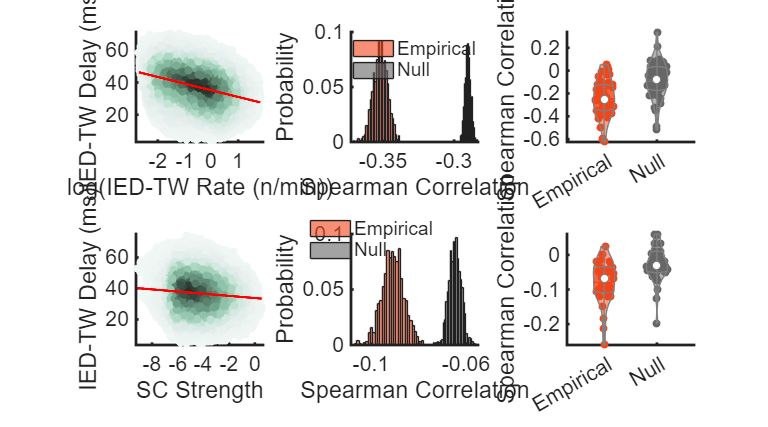

nullStr = cell(length(R_fibNtwD_rED_null), 1);
for n = 1:length(nullStr)
    nullStr{n} = 'Null';
end
R = [R_fibNtwD_rED_true; R_fibNtwD_rED_null];
Origin = [trueStr; nullStr];
subplot(2, 3, 6);
vs = violinplot(R, Origin, 'QuartileStyle','shadow', ...
    'Width', 0.2, 'GroupOrder', {'Empirical', 'Null'}, ...
    'ViolinColor', [0.95, 0.27, 0.1; 0.4, 0.4, 0.4], ...
    'ShowMean', true, 'ViolinAlpha', 0.5, ...
    'MarkerSize', 35);
xlim([0.3, 2.7]); 
ylabel('Spearman Correlation');
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);

x = R_fibNtwD_rED_true(:); 
y = R_fibNtwD_rED_null(:);
[p, h, stats] = ranksum(x, y, 'tail', 'both', 'method', 'approximate');
z = stats.zval; 
cliffDelta = f_cliff_delta(x, y);
df = length(x)+length(y)-2;
disp(['p = ', num2str(p), ' z = ', num2str(z), ...
    ' Cliff Delta = ', num2str(cliffDelta), ' df = ', num2str(df)]);

p = 0.00053497 z = -3.4626 Cliff Delta = -0.49679 df = 64
